Function

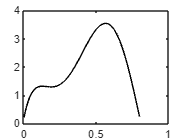

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with simpson 1/3 rule with ns = 1

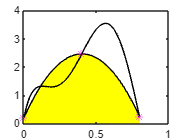

ns = 1;
x = linspace(0, 0.8, 2*ns+1);
y = f(x);

p2 = polyfit(x,y,2);
yy2 = polyval(p2,xx);

figure
area(xx,yy2,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
hold on
plot(xx,yy,'k-')
hold off


p = p2

p =   -14.0000   11.2400    0.2000


q = polyint(p);
I1 = diff(polyval(q, [a b]))

I1 = 1.3675

et = (Itrue - I1)/Itrue*100

et = 16.6450

Plot original function along with simpson 1/3 rule with ns = 4

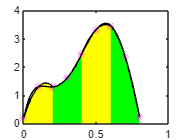

ns = 4;
x = linspace(0, 0.8, 2*ns+1);
y = f(x);

figure
color = ['g','y'];

sum = 0;

for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = x(il:ir);
    newy = y(il:ir);

    h = (newx(3) - newx(1)) / 2;

    p2 = polyfit(newx, newy, 2);
    xx2 = linspace(x(il), x(ir));
    yy2 = polyval(p2, xx2);

    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on

    Dy0 = f(newx(3));
    Dy1 = f(newx(2)).*4;
    Dy2 = f(newx(1));

    I4 = h/3 * (Dy0 + Dy1 + Dy2);
    sum = sum + I4;
end

plot(xx,yy,'k-')
hold off


I4 = sum

I4 = 1.6395

et = (Itrue - I4)/Itrue*100

et = 0.0650

| et | < 1

ns = 0;
et = 1

et = 1

while et >= 1

    ns = ns + 1;
    x = linspace(0, 0.8, 2*ns+1);
    y = f(x);
    
    sum = 0;
    
    for i = 1:ns
        il = 2*(i-1)+1;
        ir = 2*i+1;
        newx = x(il:ir);
        newy = y(il:ir);

        h = (newx(3) - newx(1)) / 2;
    
        p2 = polyfit(newx, newy, 2);
        xx2 = linspace(x(il), x(ir));
        yy2 = polyval(p2, xx2);
    
        Dy0 = f(newx(3));
        Dy1 = f(newx(2)).*4;
        Dy2 = f(newx(1));
    
        I4 = h/3 * (Dy0 + Dy1 + Dy2);
        sum = sum + I4;
    end
    
    I = sum
    et = (Itrue - I )/Itrue*100
end

I = 1.3675

et = 16.6450

I = 1.6235

et = 1.0403

I = 1.6372

et = 0.2055

ns

ns = 3